1.函数

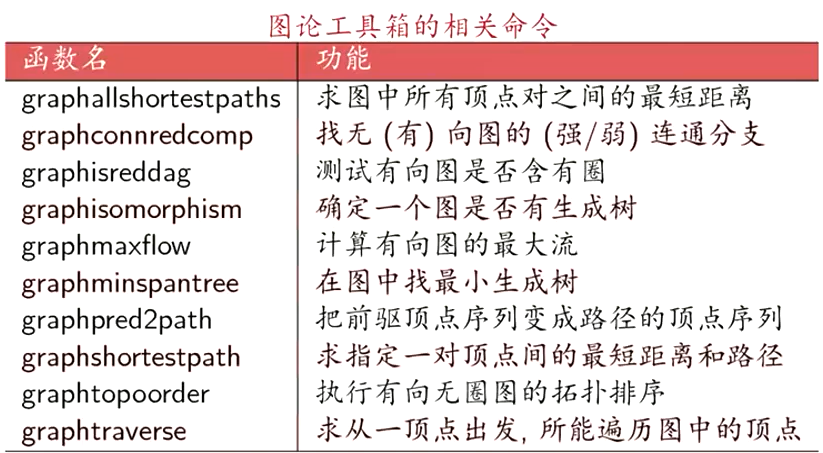

2.数据结构

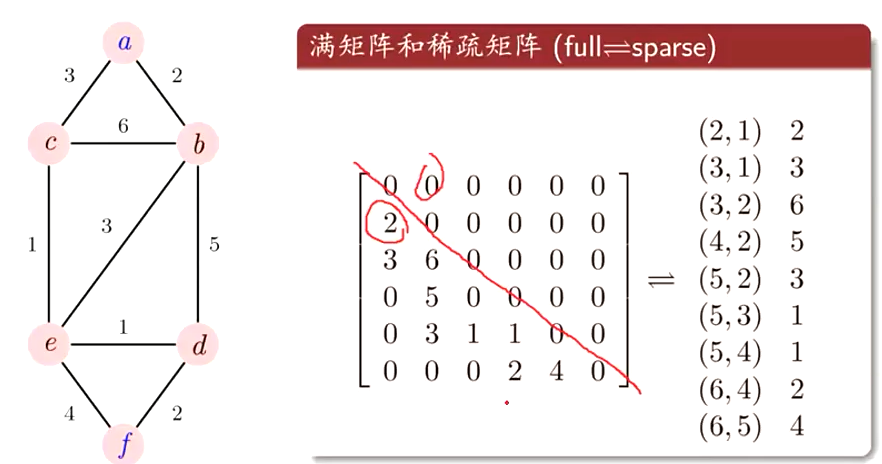

[a,b,c,d,e,f]=deal(1,2,3,4,5,6);
w=[0 2 3 0 0 0
   2 0 6 5 3 0
   3 6 0 0 1 0
   0 5 0 0 1 2
   0 3 1 1 0 4
   0 0 0 2 4 0];
W=sparse(w);
[dist,path,pred]=graphshortestpath(W,a,f)

dist = 7

path =      1     3     5     4     6


pred =      0     1     1     5     3     4


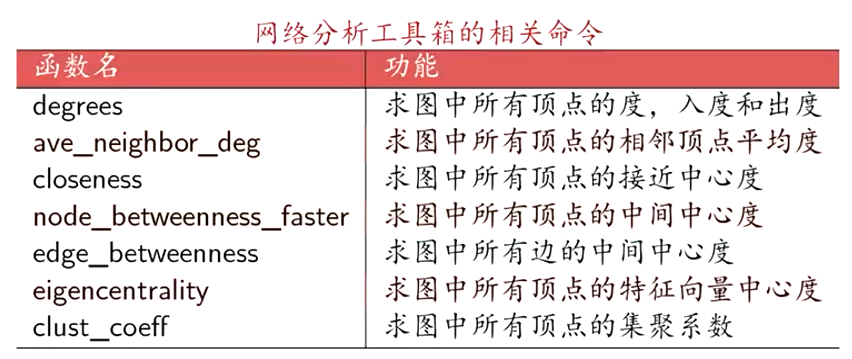

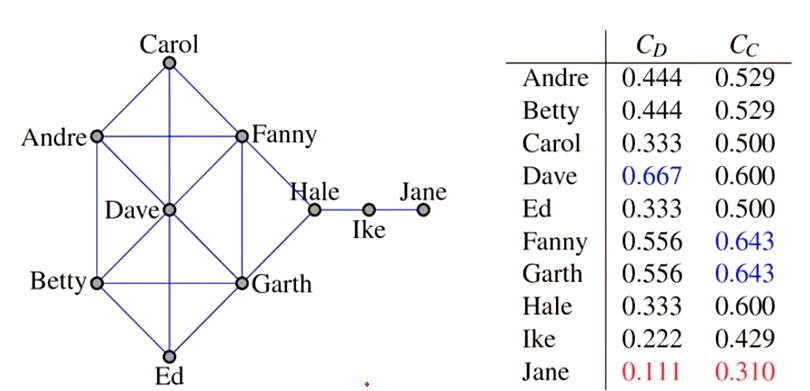

n=10;
Andre=1;Betty=2;Carol=3;Dave=4;Ed=5;
Fanny=6;Garth=7;Hale=8;Ike=9;Jane=10;
A=zeros(n);
A(Andre,[Betty,Carol,Dave,Fanny])=1;
A(Betty,[Andre,Dave,Ed,Garth])=1;
A(Carol,[Andre,Dave,Fanny])=1;
A(Dave,[Andre,Betty,Carol,Ed,Fanny,Garth])=1;
A(Ed,[Betty,Dave,Garth])=1;
A(Fanny,[Andre,Carol,Dave,Garth,Hale])=1;
A(Garth,[Betty,Dave,Ed,Fanny,Hale])=1;
A(Hale,[Fanny,Garth,Ike])=1;
A(Ike,[Hale,Jane])=1;
A(Jane,[Ike])=1;
B=graph(A)

B =   graph with properties:

    Edges: [18×2 table]
    Nodes: [10×0 table]


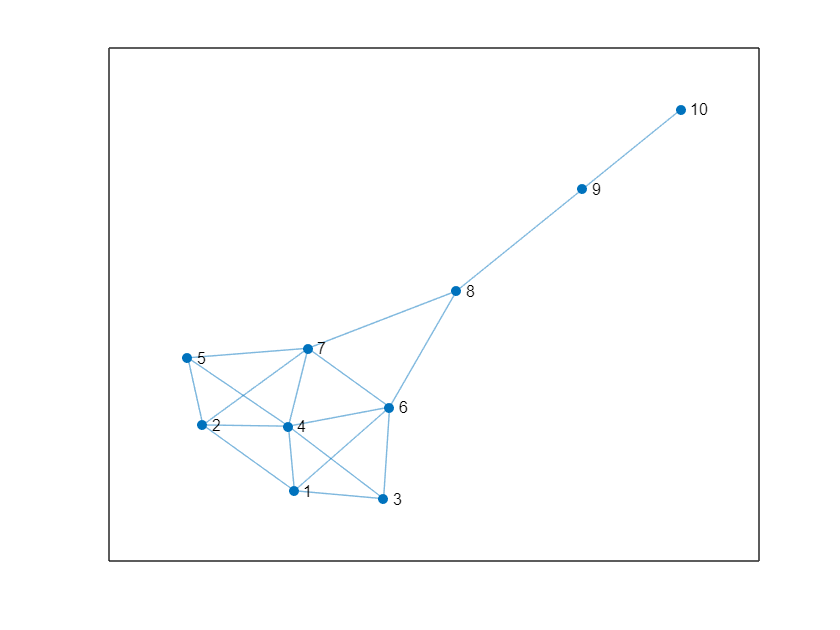

plot(B)

Cd=degree(B)'/(n-1)

Cd =     0.4444    0.4444    0.3333    0.6667    0.3333    0.5556    0.5556    0.3333    0.2222    0.1111


Cc=centrality(B,'closeness')*(n-1)

Cc =     0.5294
    0.5294
    0.5000
    0.6000
    0.5000
    0.6429
    0.6429
    0.6000
    0.4286
    0.3103


3.最短路径

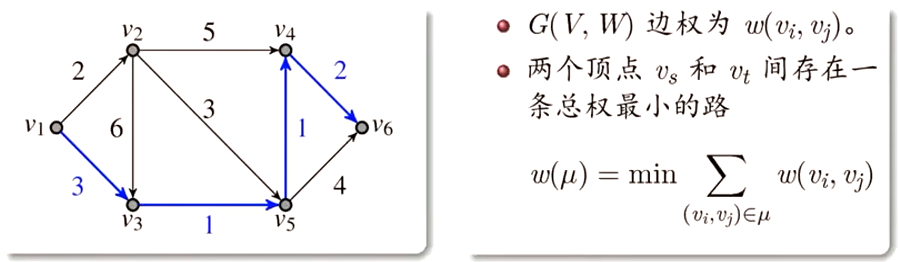

w=[0 2 3 0 0 0
   2 0 6 5 3 0
   3 6 0 0 1 0
   0 5 0 0 1 2
   0 3 1 1 0 4
   0 0 0 2 4 0];
W=sparse(w);
[dist,path,pred]=graphshortestpath(W,1,6)

dist = 7

path =      1     3     5     4     6


pred =      0     1     1     5     3     4


4.最小生成树

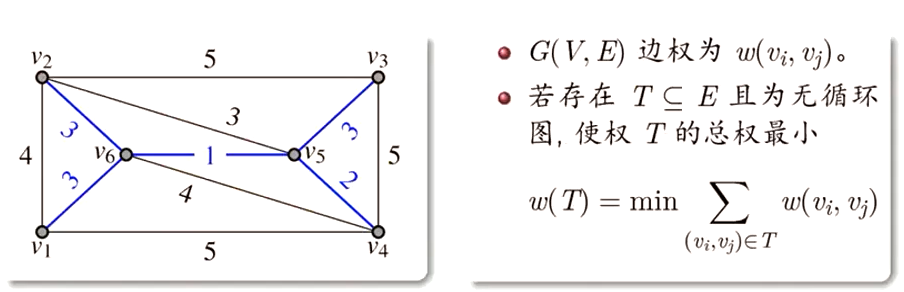

w=[0 4 inf 5 inf 3
   4 0 5 inf 3 3
   inf 5 0 5 3 inf
   5 inf 5 0 2 4
   inf 3 3 2 0 1
   3 3 inf 4 1 0];
W=sparse(w);
[ST,pred]=graphminspantree(W)

ST =    (6,1)        3
   (6,2)        3
   (5,3)        3
   (5,4)        2
   (6,5)        1


pred =      0     6     5     5     6     1


5.最短（Hamilton）回路

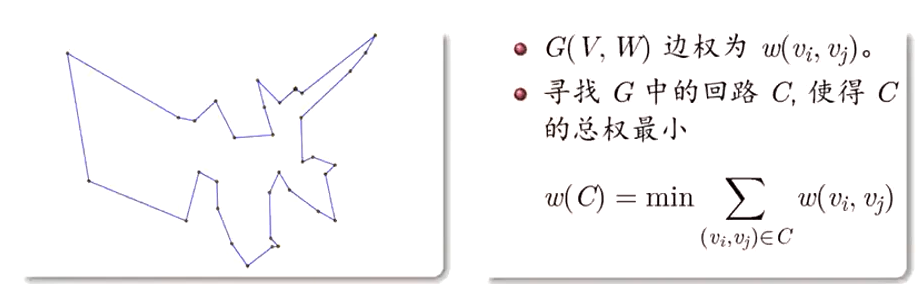

% R=6378.137;
% dist=zeros(n);
% for i=1:n
%     for j=i+1:n
%         dist(i,j)=distance(lat(i),lon(i),lat(j),lon(j),R);
%     end
% end
% [order,totdist]=minhamiltonpath(dist)